# Plan Obstacle-Free Path in Grid Map Using A-Star Path Planner

Plan the shortest collision-free path through an obstacle grid map using the A* path planning algorithm.

Generate a [binaryOccupancyMap](docid:nav_ref#bunq527) object with randomly scattered obstacles using the [mapClutter](docid:nav_ref#mw_57c313c8-90d1-4eb0-bd09-a2181b500da4) function.

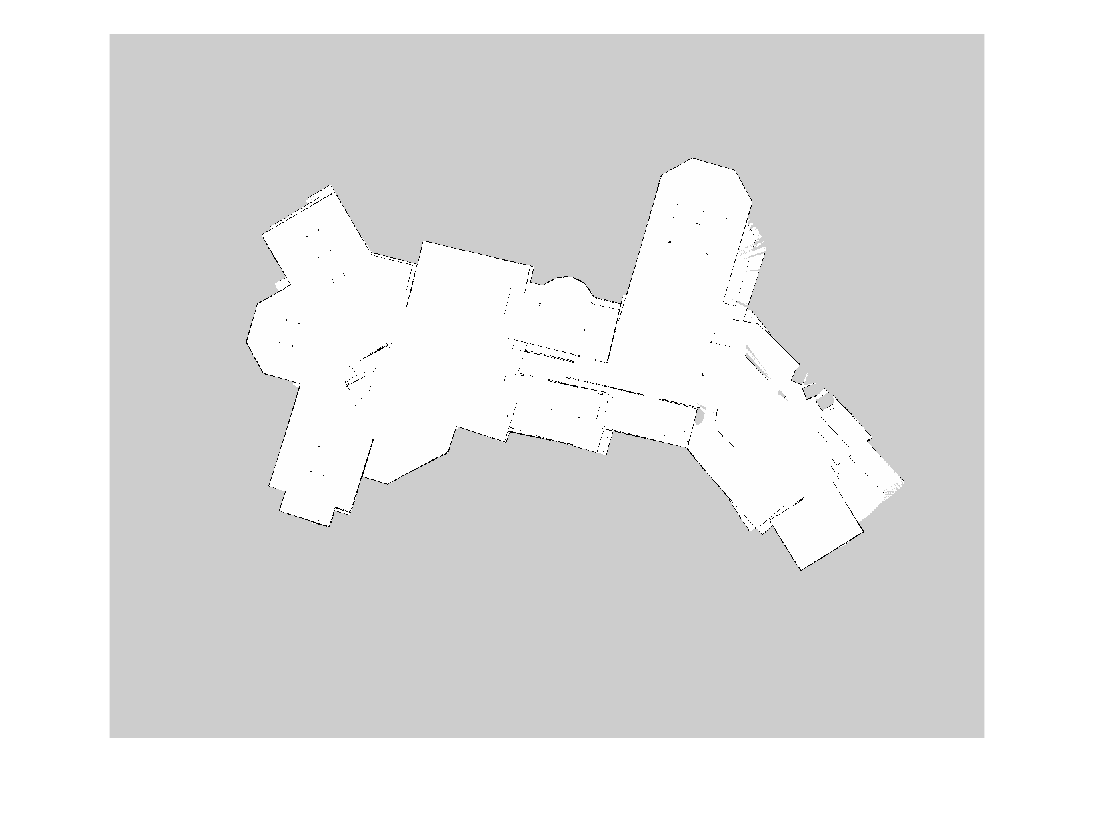

imageCropped=imread('C:\Users\Tejal/Downloads/Office.pgm');
imshow(imageCropped)

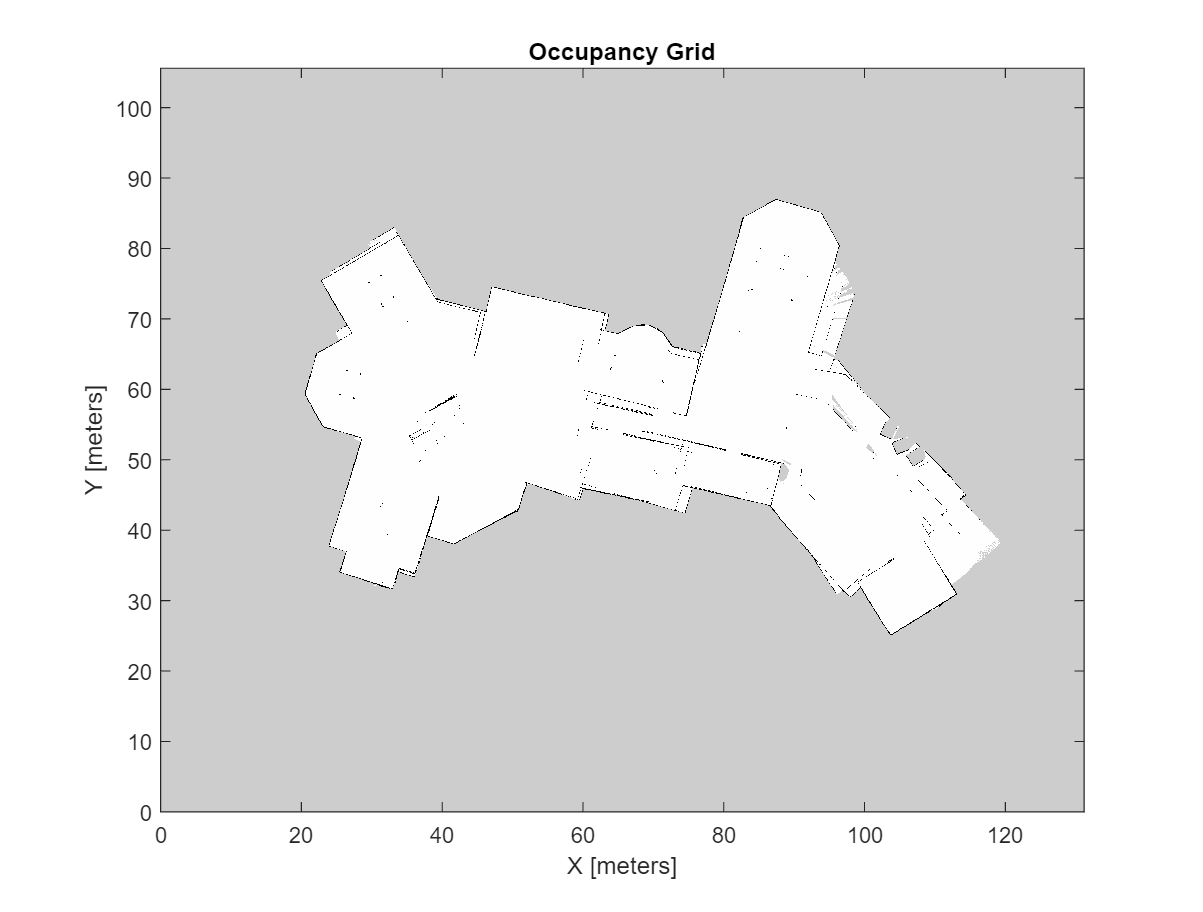

imageNorm=double(imageCropped)/255;
imageOcc=1-imageNorm;
map=occupancyMap(imageOcc,20);
load('mapredout.mat')
show(map)

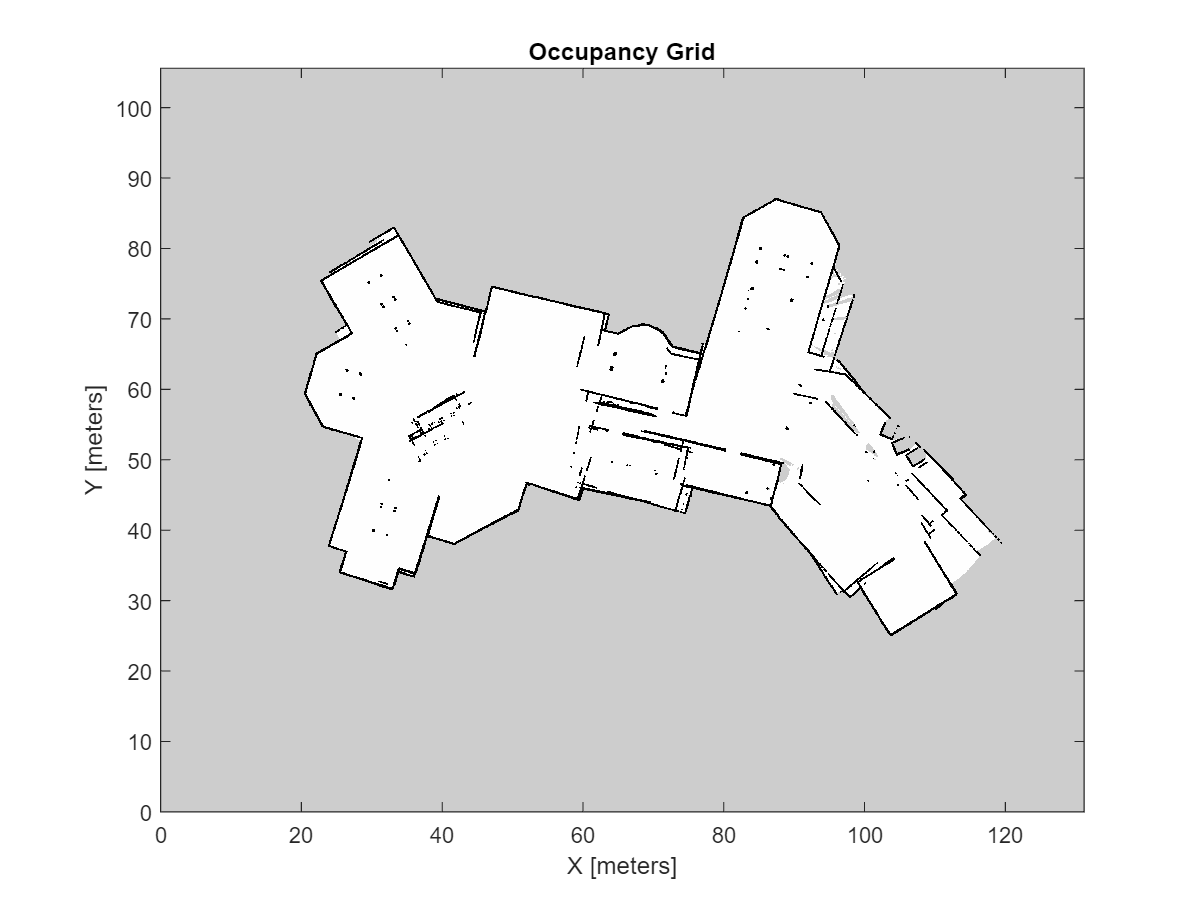

inflate(map,0.1)
show(map)

rng('default');
%map = mapClutter;

Use the map to create a [plannerAStarGrid](docid:nav_ref#mw_3ec19c13-18c8-4cdf-a9e0-9c7327e42aed) object.

planner = plannerAStarGrid(map);

Define the start and goal points.

start = [1300,700];
goal = [700,1250];

Plan a path from the start point to the goal point.

plan(planner,start,goal);

Visualize the path and the explored nodes using the [show](docid:nav_ref#mw_cf5e26b3-7a0e-4f3b-8783-33b42e0d8fab) object function.

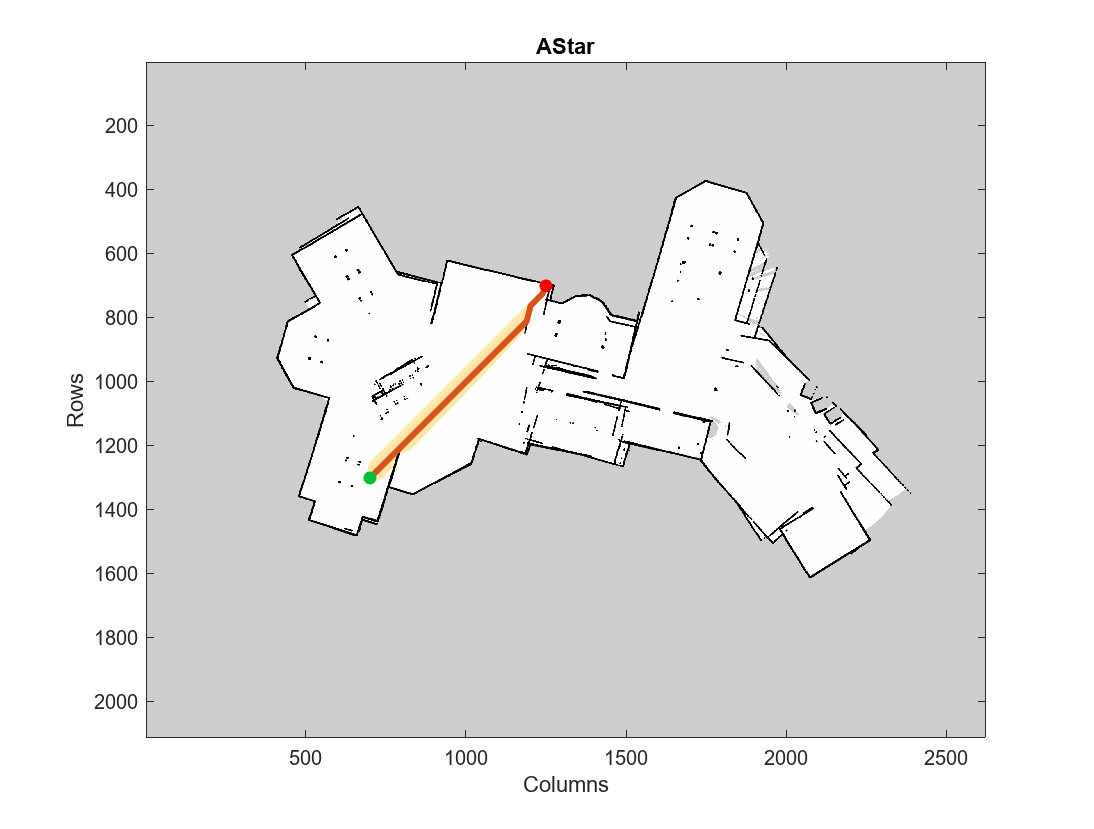

show(planner)

*Copyright 2020 The MathWorks, Inc.*